load("/media/hdd/github/compCogNeuro_codes/data/subsetData(1).mat")

oldcfg = cfg; 
lay = cfg.layout;

cfg = ft_databrowser(cfg,data);

Unrecognized field name "topolabel".

Error in ft_databrowser (line 312)
    tmpcfg.channel = data.topolabel;

cfg

cfg = struct with fields:
                  elec: [1×1 struct]
              trialdef: [1×1 struct]
                   trl: []
               dataset: '/jukebox/cohen/mkvan/eeg/ddm_eeg/DOT008/fieldtrip/DOT008_session2.mat'
           trackconfig: 'off'
           checkconfig: 'loose'
             checksize: 100000
          showcallinfo: 'yes'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
        trackparaminfo: 'no'
               preproc: [1×1 struct]
                  ylim: [-50.1000 50.1000]
             artfctdef: [1×1 struct]
         selectfeature: {'visual'}
            selectmode: 'markartifact'
             blocksize: 1.5000
                selfun: {'simpleFFT'  'multiplotER'  'topoplotER'  'topoplotVAR'  'movieplotER'}
                selcfg: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
           colorgroups: 'sequential'
              eegscale: []
              eogscale: []
              ecgscale: []
              emgscale: []
       

cfg.artfctdef.reject = "partial";
cleandata = ft_rejectartifact(cfg,data);

rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   0 trials with zeros
filled parts of   0 trials with a specified value
resulting 250 trials


the input is raw data with 116 channels and 250 trials
the call to "ft_redefinetrial" took 1 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_rejectartifact" took 2 seconds and required the additional allocation of an estimated 1 MB


cfg = [];
cfg.channel = [2:116]; % remove the first channel (EOG) to ensure ICA
% goes well
ic_data =ft_componentanalysis(cfg,cleandata);

the input is raw data with 116 channels and 250 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
baseline correcting data 
scaling data with 1 over 37.593770
concatenating data
concatenating trials...
Concatenating trial 250 from 250

concatenated data matrix size 115x93750
starting decomposition using runica

Input data size [115,93750] = 115 channels, 93750 frames
Finding 115 ICA components using logistic ICA.
Decomposing 7 frames per ICA weight ((13225)^2 = 93750 weights, Initial learning rate will be 0.001, block size 58.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -6.27918 to 7.32528
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.001000, wch

cfg = [];
cfg.viewmode = "component";
cfg.continuous = "yes";
cfg.blocksize = 30;
cfg.channel = 1:10;
cfg.layout = oldcfg.layout;

load("/media/hdd/github/compCogNeuro_codes/data/backupdata.mat")

cfg = ft_databrowser(cfg,ic_data);

the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is component data with 115 components and 115 original channels
the input is raw data with 115 channels and 217 trials


detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 4 seconds and required the additional allocation of an estimated 0 MB


cfg

cfg = struct with fields:
              viewmode: "component"
            continuous: "yes"
             blocksize: 30
               channel: {10×1 cell}
                layout: 'empty - this was cleared by checkconfig'
            trackusage: '757DE3C0'
           trackconfig: 'off'
           checkconfig: 'loose'
             checkpath: 'pedantic'
             checksize: 100000
              showlogo: 'yes'
          showcallinfo: 'yes'
                 debug: 'no'
     outputfilepresent: 'overwrite'
         trackcallinfo: 'yes'
         trackdatainfo: 'no'
         tracktimeinfo: 'yes'
          trackmeminfo: 'yes'
               toolbox: [1×1 struct]
          notification: [1×1 struct]
              progress: [1×1 struct]
              callinfo: [1×1 struct]
               version: [1×1 struct]
               preproc: [1×1 struct]
                  ylim: [-0.1080 0.1080]
                  zlim: 'maxmin'
             artfctdef: [1×1 struct]
            selectmode: 'markartifact'


cfg = [];
cfg.component = [4 21 24 31 33 52 64 89 90 93 98 103 114];
data_iccleaned = ft_rejectcomponent(cfg,ic_data);

removing 13 components
keeping 102 components


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trials
processing trial 217 from 217

the call to "ft_rejectcomponent" took 0 seconds and required the additional allocation of an estimated 0 MB


%cfg2 = ft_databrowser(cfg,data_iccleaned);

the input is raw data with 115 channels and 217 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 3 seconds and required the additional allocation of an estimated 0 MB


cfg = ft_databrowser(cfg,data_iccleaned);

the input is raw data with 115 channels and 217 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 4 seconds and required the additional allocation of an estimated 88 MB


cfg.bsfilter = "yes";
cfg.bsfreq = [59 61];
data_preprocessed = ft_preprocessing(cfg, data_iccleaned)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 217 from 217

the call to "ft_preprocessing" took 3 seconds and required the additional allocation of an estimated 0 MB


data_preprocessed = struct with fields:
       fsample: 250
    sampleinfo: [217×2 double]
     trialinfo: [217×3 double]
         trial: {1×217 cell}
          time: {1×217 cell}
         label: {115×1 cell}
           cfg: [1×1 struct]


cfg = ft_databrowser(cfg,data_preprocessed);

the input is raw data with 115 channels and 217 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 3 seconds and required the additional allocation of an estimated 55 MB


cfg.preproc.hpfilter = "yes"; cfg.preproc.hpfreq = [0.2];
data_preprocessed = ft_preprocessing(cfg, data_preprocessed)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 217 from 217

the call to "ft_preprocessing" took 3 seconds and required the additional allocation of an estimated 0 MB


data_preprocessed = struct with fields:
       fsample: 250
    sampleinfo: [217×2 double]
     trialinfo: [217×3 double]
         trial: {1×217 cell}
          time: {1×217 cell}
         label: {115×1 cell}
           cfg: [1×1 struct]


cfg2 = ft_databrowser(cfg,data_preprocessed);

the input is raw data with 115 channels and 217 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 109 seconds and required the additional allocation of an estimated 0 MB


% Till here.

load("/media/hdd/github/compCogNeuro_codes/data/datForAnal.mat")

oldcfg = cfg; 
%lay = cfg.layout;

cfg = ft_databrowser(cfg,hpdat);

the input is raw data with 115 channels and 1031 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

the call to "ft_databrowser" took 2 seconds and required the additional allocation of an estimated 45 MB


hpdat

hpdat = struct with fields:
           hdr: [1×1 struct]
       fsample: 250
          elec: [1×1 struct]
    sampleinfo: [1031×2 double]
     trialinfo: [1031×3 double]
         trial: {1×1031 cell}
          time: {1×1031 cell}
         label: {115×1 cell}
           cfg: [1×1 struct]


tempinfo = hpdat.trialinfo(:, 2)

tempinfo =      8
     8
     8
     8
     8
     8
     8
     8
     8
     8


unique(highCohTrials)

ans = 2×1 logical array
   0
   1


cfg = [];
cfg.channel = 'all';
cfg.trials = highCohTrials';
cfg.keeptrials = 1;
timelockHigh = ft_timelockanalysis(cfg,hpdat);

the input is raw data with 115 channels and 1031 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 171 MB



cfg = [];
cfg.channel = 'all';
cfg.trials = lowCohTrials';
cfg.keeptrials = 1;
timelockLow = ft_timelockanalysis(cfg,hpdat);

the input is raw data with 115 channels and 1031 trials


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 174 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 174 MB


timelockHigh

timelockHigh = struct with fields:
          time: [-0.4960 -0.4920 -0.4880 -0.4840 -0.4800 -0.4760 -0.4720 -0.4680 -0.4640 -0.4600 -0.4560 -0.4520 -0.4480 -0.4440 -0.4400 -0.4360 -0.4320 -0.4280 -0.4240 -0.4200 -0.4160 -0.4120 -0.4080 -0.4040 -0.4000 -0.3960 -0.3920 -0.3880 -0.3840 … ]
         label: {115×1 cell}
          elec: [1×1 struct]
    sampleinfo: [528×2 double]
         trial: [528×115×375 double]
     trialinfo: [528×3 double]
        dimord: 'rpt_chan_time'
           cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


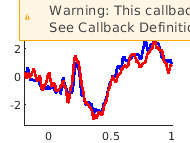

cfg = [];
cfg.xlim = [-0.2 1.0];
cfg.ylim = [-3.5 3];
cfg.channel = 'CZ';
cfg.fontsize = 18;
cfg.linewidth = 2;
ft_singleplotER(cfg,timelockHigh,timelockLow);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_multiplotER" took 2 seconds and required the additional allocation of an estimated 40 MB


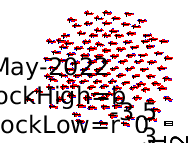

cfg.channel = "all";
cfg.layout = lay;
ft_multiplotER(cfg,timelockHigh,timelockLow);

the input is raw data with 115 channels and 1031 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


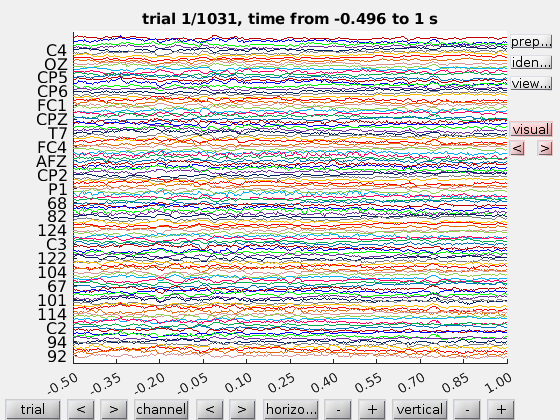

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

%ft_databrowser(cfg, hpdat)

the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


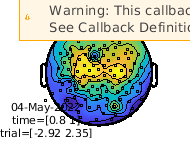

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotER" took 0 seconds and required the additional allocation of an estimated 0 MB


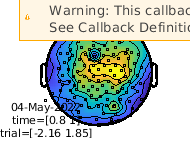

cfg = [];
cfg.xlim = [0.8 1];
cfg.layout = lay;
figure; ft_topoplotER(cfg,timelockHigh,timelockLow)

cfg = [];
cfg.xlim = [0 1];
cfg.channel = 'CZ';
cfg.layout = lay;
cfg.baseline = [-0.2 0]

cfg = struct with fields:
        xlim: [0 1]
     channel: 'CZ'
      layout: [1×1 struct]
    baseline: [-0.2000 0]


the input is timelock data with 115 channels and 375 timebins
applying baseline correction on each individual trial
the call to "ft_timelockbaseline" took 0 seconds and required the additional allocation of an estimated 174 MB


the input is timelock data with 115 channels and 375 timebins
applying baseline correction on each individual trial
the call to "ft_timelockbaseline" took 0 seconds and required the additional allocation of an estimated 165 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_singleplotER" took 0 seconds and required the additional allocation of an estimated 339 MB


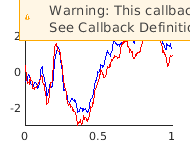

ft_singleplotER(cfg,timelockHigh,timelockLow);

design = [ones(1,size(timelockHigh.trial,1)) 2*ones(1,size(timelockLow.trial,1))];
cfg.design = design;
cfg.ivar = 1;

cfg = [];
cfg.neighbourdist = 3.5;
cfg.method = 'distance';
cfg.elec = oldcfg.elec;
neighbours = ft_prepare_neighbours(cfg,timelockHigh);

Your data and configuration allow for multiple sensor definitions.


there are on average 5.9 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds and required the additional allocation of an estimated 0 MB


cfg = [];
cfg.method = 'montecarlo';
cfg.parameter = 'trial';
cfg.numrandomization = 200;
cfg.correctm = 'cluster';
cfg.alpha = 0.05;
cfg.tail = 0;
cfg.statistic = 'indepsamplesT';
cfg.clusterstatistic = 'maxsum';
cfg.clusterthreshold = 'parametric';
cfg.clusteralpha = 0.05;
cfg.neighbours = neighbours;
cfg.design = design;
cfg.ivar = 1;
stat = ft_timelockstatistics(cfg,timelockHigh,timelockLow);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


using specified neighbours for the channels
there are on average 5.9 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds and required the additional allocation of an estimated 0 MB
using "ft_statistics_montecarlo" for the statistical testing


using "ft_statfun_indepsamplesT" for the single-sample statistics
constructing randomized design
total number of measurements     = 1031
total number of variables        = 1
number of independent variables  = 1
number of unit variables         = 0
number of within-cell variables  = 0
number of control variables      = 0
using a permutation resampling approach
computing a parametric threshold for clustering
computing statistic
estimated time per randomization is 1.04 seconds
computing statistic 200 from 200

found 65 positive clusters in observed data
found 74 negative clusters in observed data
computing clusters for the thresholded test statistic computed from the randomized design
computing clusters in randomization 200 from 200

using a cluster-based method for multiple comparison correction
the returned probabilities and the thresholded mask are corrected for multiple comparisons
the call to "ft_timelockstatistics" took 94 seconds and required the additional allocation of an estimat

the input is timelock data with 115 channels and 375 timebins


creating layout from data.elec
creating layout for ext1020 system


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB


Error using getdimord
field "trial" not present in data

Error in ft_clusterplot (line 128)
dimord = getdimord(stat, cfg.parameter);

stat

stat = struct with fields:
                   prob: [115×375 double]
            posclusters: [1×65 struct]
    posclusterslabelmat: [115×375 double]
        posdistribution: [236.8631 723.1248 1.7453e+03 174.1970 244.8518 243.9366 860.2379 1.4824e+03 356.2967 1.0965e+03 197.0780 178.0497 512.5229 352.7783 390.1646 488.8519 183.7912 541.9085 221.7300 344.4207 719.2190 618.2384 306.1552 680.3671 … ]
            negclusters: [1×74 struct]
    negclusterslabelmat: [115×375 double]
        negdistribution: [-401.3562 -375.9451 -2.0141e+03 -263.4795 -240.0264 -674.0735 -512.4865 -801.8057 -261.5346 -2.6537e+03 -399.1815 -440.5385 -331.2214 -302.5165 -620.1677 -431.1848 -460.6318 -373.2599 -267.0544 -197.8380 -574.7675 -532.0060 … ]
                cirange: [115×375 double]
                   mask: [115×375 logical]
                   stat: [115×375 double]
                    ref: [115×375 double]
                 dimord: 'chan_time'
                   elec: [1×1 struct]
                  l

the input is timelock data with 115 channels and 375 timebins


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 2 MB
There are 2 clusters smaller than alpha (0.1)
Positive cluster: 1, pvalue: 0.089552 (+), t = 0.712 to 0.836
Negative cluster: 1, pvalue: 0.079602 (+), t = 0.728 to 0.82
making subplots...
making subplot 1 from 32


making subplot 2 from 32


making subplot 3 from 32


making subplot 4 from 32


making subplot 5 from 32


making subplot 6 from 32


making subplot 7 from 32


making subplot 8 from 32


making subplot 9 from 32


making subplot 10 from 32


making subplot 11 from 32


making subplot 12 from 32


making subplot 13 from 32


making subplot 14 from 32


making subplot 15 from 32


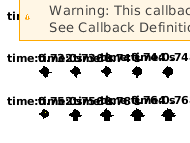

making subplot 16 from 32


making subplot 17 from 32


making subplot 18 from 32


making subplot 19 from 32


making subplot 20 from 32


making subplot 21 from 32


making subplot 22 from 32


making subplot 23 from 32


making subplot 24 from 32


making subplot 25 from 32


making subplot 26 from 32


making subplot 27 from 32


making subplot 28 from 32


making subplot 29 from 32


making subplot 30 from 32


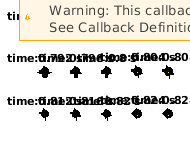

making subplot 31 from 32


making subplot 32 from 32


making subplot 0 from 32



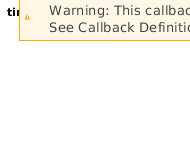

the call to "ft_clusterplot" took 13 seconds and required the additional allocation of an estimated 15 MB


cfg = [];
cfg.alpha = 0.1;
%cfg.channel = 'CZ';
cfg.parameter = 'prob';
cfg.layout = lay;
ft_clusterplot(cfg,stat);